# スカログラムとDeep CNNによる異音判定

以下では、1つの健全な状態と7つの異なる異常の状態を有する空気圧縮機の異音判定のアルゴリズムを示しています。

音声データはいずれも16 kHzで取得されています。

スカログラムとDCNNを活用した異音判定の例題は以下のページをご参照ください。

[https://jp.mathworks.com/help/wavelet/ug/classify-time-series-using-wavelet-analysis-and-deep-learning.html](https://jp.mathworks.com/help/wavelet/ug/classify-time-series-using-wavelet-analysis-and-deep-learning.html)

信号アナライザーによる時間周波数解析は以下のページをご参照ください。

[https://jp.mathworks.com/help/signal/ref/signalanalyzer-app.html](https://jp.mathworks.com/help/signal/ref/signalanalyzer-app.html)

デモに必要な製品一覧：

- Audio Toolbox™

- DSP System Toolbox™

- Signal Processing Toolbox™

- Deep Learning Toolbox™

- Wavelet Toolbox™

- Image Processing Toolbox™

## 初期化

clear; close all;
format short; format compact;
% 乱数群の制御
rng('default');

## データの読み込み

url = 'https://www.mathworks.com/supportfiles/audio/AirCompressorDataset/AirCompressorDataset.zip';
downloadFolder = fullfile(tempdir,'aircompressordataset');
datasetLocation = tempdir;

if ~exist(fullfile(tempdir,'AirCompressorDataSet'),'dir')
    loc = websave(downloadFolder,url);
    unzip(loc,fullfile(tempdir,'AirCompressorDataSet'))
end

ads = audioDatastore(downloadFolder,'IncludeSubfolders',true,...
    'LabelSource','foldernames'); %* フォルダ名 = ラベル

## 連続Wavelet変換のフィルタバンクの設定

fb = cwtfilterbank('SignalLength',25000,'SamplingFrequency',16*10^3);

## データの可視化

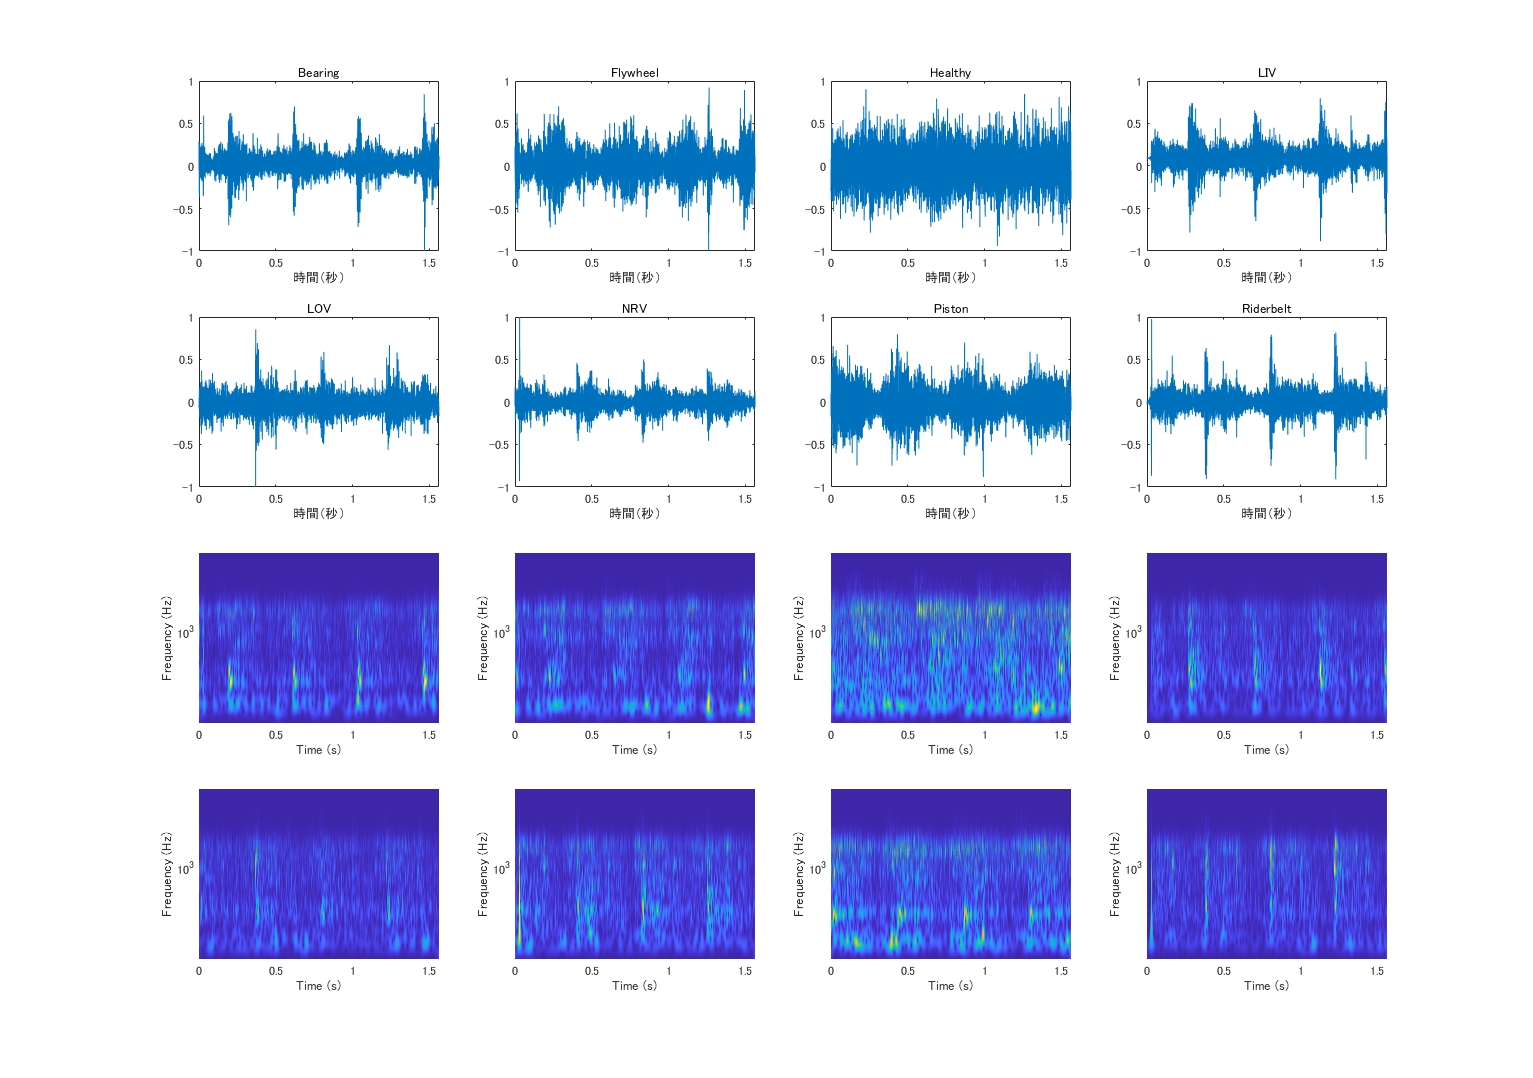

imageRoot = fullfile(pwd,'image');
if ~exist(imageRoot,"dir")
    mkdir(imageRoot)
end

epsil = 1e-6;

uniqueLabels = unique(ads.Labels);
figure('Name','Imported data','Units','Normalized','Position',[0.05, 0.25, 0.80, 1]);
for n = 1:numel(uniqueLabels)
    idx = find(ads.Labels==uniqueLabels(n),1);
    [x,fs] = audioread(ads.Files{idx});
    idx = round(length(x)/2);
    x = x(1:idx);
    t = (0:size(x,1)-1)/fs;
    
    subplot(4,4,n);
    plot(t,x);
    xlabel('時間（秒）')
    title(string(uniqueLabels(n)));
    
    [cfs, frq] = wt(fb,x); %* scalogram
    cfs = abs(cfs);
    
    %* 範囲の抽出
    idx = frq>100; %* スカログラムより100 Hz以下は変化が観察されない
    frq = frq(idx);
    cfs = cfs(idx,:);
    
    im = ind2rgb(im2uint8(rescale(cfs)),jet(128));
    P = imresize(im, [96, 64]);
    
    subplot(4,4,n+8);
    pcolor(t,frq,cfs);
    set(gca,'yscale','log'); shading interp; axis tight;
    xlabel('Time (s)'); ylabel('Frequency (Hz)')
    
    imgLoc = fullfile(imageRoot,char(uniqueLabels(n)));
    if ~exist(imgLoc,"dir")
        mkdir(imgLoc)
    end
end

## データの作成

reset(ads)
k = 0;
tic
while hasdata(ads)
    
    k = k+1;
    
    [audioIn,fileInfo] = read(ads);
    x = audioIn(:);
    
    idx = round(length(x)/2);
    x = x(1:idx);
    t = (0:size(x,1)-1)/fs;
    
    [cfs, frq] = wt(fb,x); %* scalogram
    cfs = abs(cfs);
    
    %* 範囲の抽出
    idx = frq>100; %* スカログラムより100 Hz以下は変化が観察されない
    frq = frq(idx);
    cfs = cfs(idx,:);
    
    im = ind2rgb(im2uint8(rescale(cfs)),jet(128));   
    imgLoc = fullfile(imageRoot,char(fileInfo.Label));
    imFileName = strcat(char(fileInfo.Label),'_',num2str(k,'%04d'),'.jpg');
    imwrite(imresize(im,[96 64]),fullfile(imgLoc,imFileName));
end
toc

経過時間は 586.839310 秒です。


## データストアの作成

ads = imageDatastore(imageRoot,...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

## データの分割：学習用 + 検証用 + テスト用

ads = shuffle(ads); %* データのシャッフル
[adsTrain,adsValidation,adsTest] = splitEachLabel(ads,0.7,0.2,0.1);

## データの構成を確認：学習用 + 検証用 + テスト用

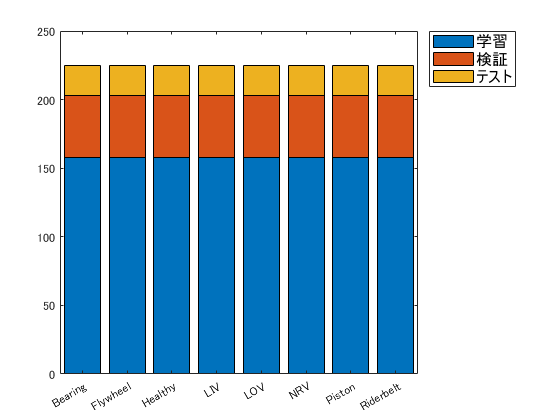

tblTrain = countEachLabel(adsTrain);
tblValidation = countEachLabel(adsValidation);
tblTest = countEachLabel(adsTest);
figure; clf;
H = bar(uniqueLabels,[tblTrain.Count, tblValidation.Count, tblTest.Count],'stacked');
legend(H,{'学習','検証','テスト'},'Location','NorthEastOutside','FontSize',12)

## ネットワークの構築

畳み込み層 x5

imageSize = [size(P,1,2) 3];

classWeights = 1./countcats(adsTrain.Labels);
classWeights = classWeights'/mean(classWeights);
numClasses = numel(categories(adsTrain.Labels));

timePoolSize = ceil(imageSize(2)/8);
dropoutProb = 0.2;
numF = 12;
layers = [
    imageInputLayer(imageSize) %* 入力層

    convolution2dLayer(3,numF,'Padding','same')  %*　畳み込み層
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same') %*　プーリング層

    convolution2dLayer(3,2*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer([1 timePoolSize])

    dropoutLayer(dropoutProb)
    fullyConnectedLayer(numClasses) %* 出力層
    softmaxLayer
    weightedClassificationLayer(classWeights)];

## 学習のオプション

miniBatchSize = 128; % ミニバッチサイズ
validationFrequency = floor(numel(adsTrain.Labels)/miniBatchSize); % 検証頻度

options = trainingOptions('sgdm', ...
    'InitialLearnRate',5e-3, ...
    'MaxEpochs',100, ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'ValidationData',adsValidation, ...
    'ValidationFrequency',validationFrequency);

## 学習の開始

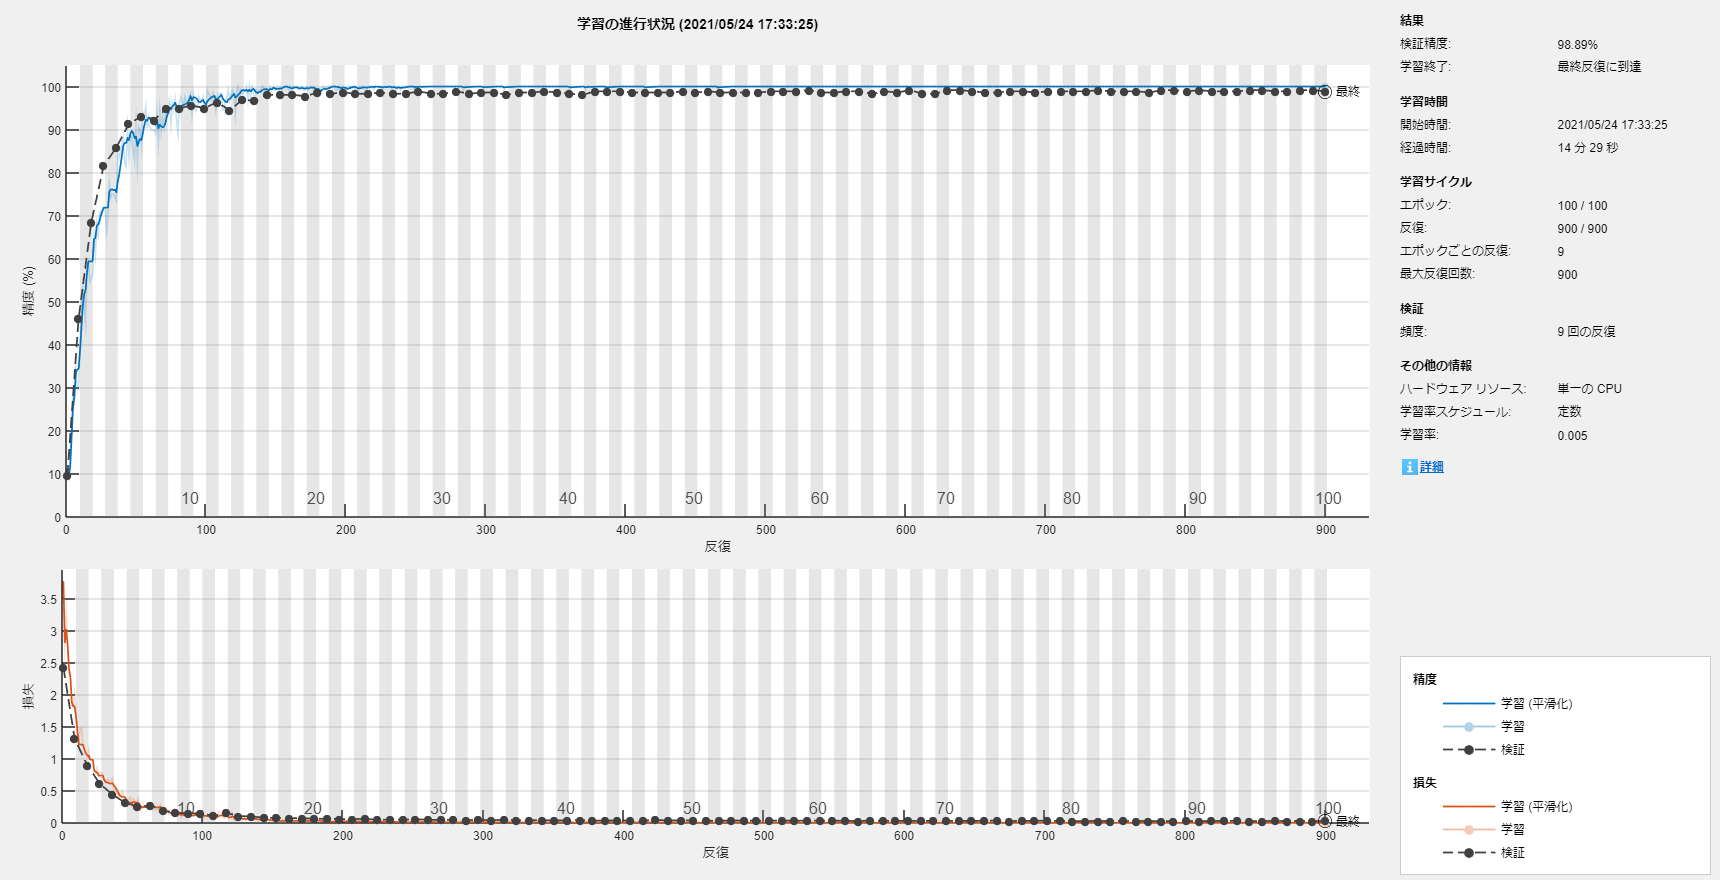

trainedNet = trainNetwork(adsTrain,layers,options);

## テスト：精度検証

tblTest

tblTest = 8×2 table
      Label      Count
    _________    _____
    Bearing       22  
    Flywheel      22  
    Healthy       22  
    LIV           22  
    LOV           22  
    NRV           22  
    Piston        22  
    Riderbelt     22  

predLabels = classify(trainedNet,adsTest);
accuracy = 100*mean(predLabels == adsTest.Labels) % 精度（%）

accuracy = 97.7273

## 混同行列

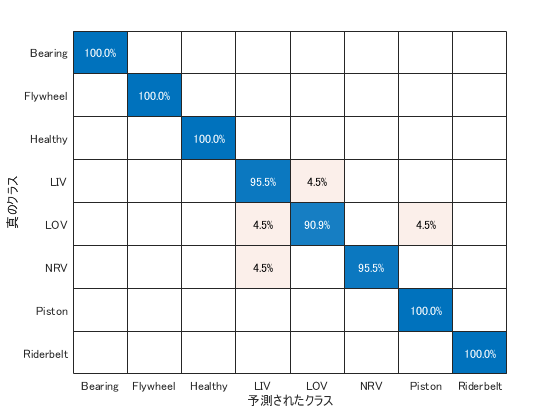

figure; clf;
confusionchart(adsTest.Labels, predLabels,"Normalization","row-normalized")

## 精度の可視化

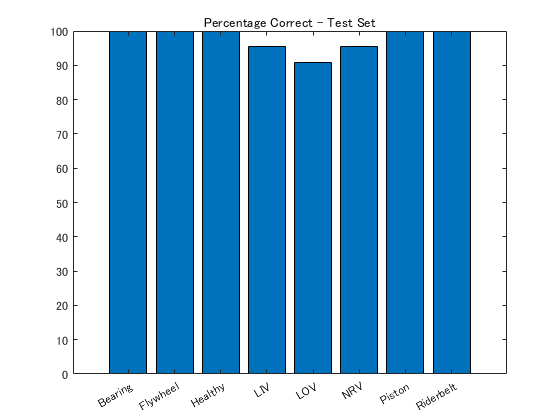

cm = confusionmat(adsTest.Labels, predLabels);
acc = diag(cm)./tblTest.Count*100;
figure; clf;
bar(acc)
set(gca,'XTickLabels',uniqueLabels);
xtickangle(gca,30);
title('Percentage Correct - Test Set');

*Copyright 2021 The MathWorks, Inc.*